# Restricted 2PN Matched filter and GW170817 detection

GW170817 was a double neutron star binary inspiral and merger that was detected in both gravitational and electromagnetic observations. In this exercise, we will apply matched filtering to conditioned data (whitened and lines removed) from the LIGO L1 detector and verify the existence of the signal in the data. The original L1 data had a large glitch in coincidence with GW170817. In the data we are using, the glitch has been cleaned out using the Bayeswave algorithm. 

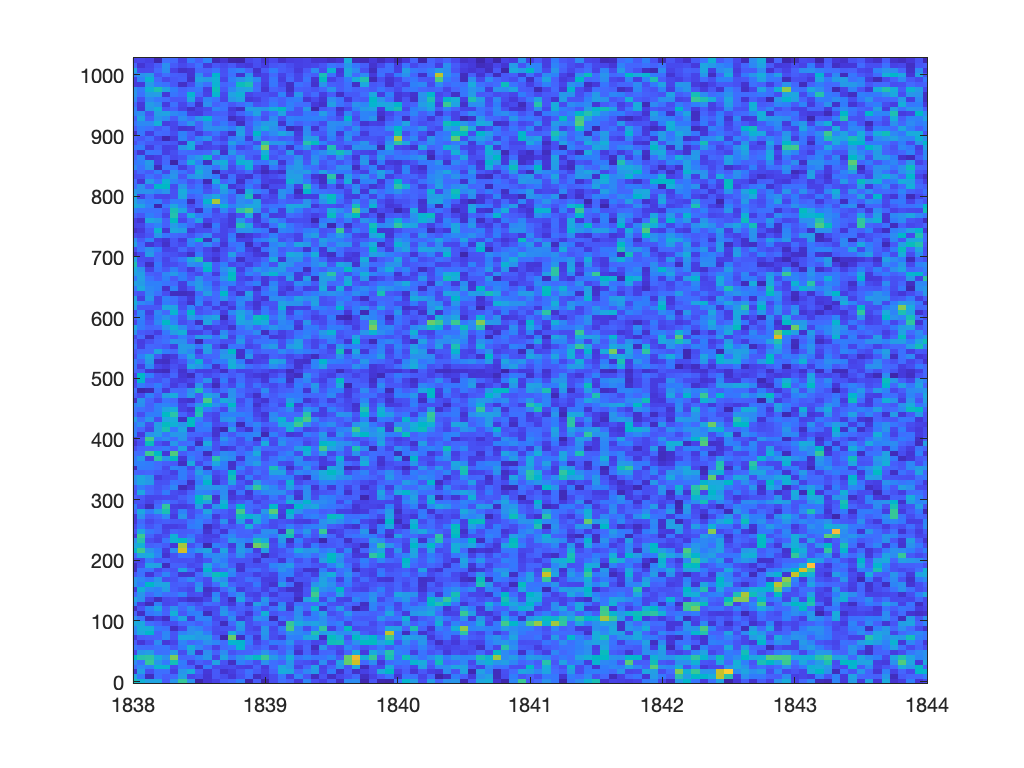

dataDirPath = ['..',filesep,'GWDATA'];

%Conditioned data file
clnCondinFile = [dataDirPath,filesep,'L-L1_LOSC_CLN_16_V1-1187007040-2048_DtrndWhtnBndStpDnsmpl.hdf5'];

%Read the strain data
clnCond_Strain = h5read(clnCondinFile,'/strain/Strain');

%Obtain the sampling frequency 
clnCond_SmplIntrvl = h5readatt(clnCondinFile,'/strain/Strain','Xspacing'); %Hz
clnCond_fsmpl = 1/clnCond_SmplIntrvl;

%Vector of sampling times
clnCond_tVec = (0:(length(clnCond_Strain)-1))/clnCond_fsmpl;

% Plot the spectrogram and zoom in around the end to 
% see the track made by GW170817
figure;
[S,F,T]=spectrogram(clnCond_Strain,256,[],[],2048);
imagesc(T,F,abs(S));axis xy
xlim([1838,1844]);

Get the whitening transfer function from the original conditioned data file. The transfer function is given only for positive frequencies. It needs to be extended to negative frequencies before it can be used in the matched filter.

%Read the conditioning Transfer function and turn into a row vector
clnCond_whtTF_half = h5read(clnCondinFile, '/strain/condTF');
clnCond_nsmpls_WhtTF_half = length(clnCond_whtTF_half);
clnCond_whtTF_half = reshape(clnCond_whtTF_half,[1,clnCond_nsmpls_WhtTF_half]);%Ensure row vector

%Complete the whitening transfer function for negative frequencies ...
clnCond_nSmpls = length(clnCond_Strain);
clnCond_whtTF = zeros(1,clnCond_nSmpls);
clnCond_whtTF(1:clnCond_nsmpls_WhtTF_half) = clnCond_whtTF_half(:)';
nsmpls_negFreq  = clnCond_nSmpls - clnCond_nsmpls_WhtTF_half;
clnCond_whtTF(end:-1:(end-nsmpls_negFreq+1)) = clnCond_whtTF_half(2:(nsmpls_negFreq+1));

## Matched filtering

We will apply a matched filter to the data with fixed mass parameters. The output of the matched filter is a quadrature sum of the outputs from two out-of-phase filters. This is the form of the GLRT for Gaussian noise after maximization over the unknown amplitude and initial phase of the signal.

Set the template parameters for matched filtering.

sigParams = struct();
sigParams.mass1 = 1.46;%1.46(+.12,-0.1);%1.4; %Solar masses
sigParams.mass2 = 1.3;%1.27(+0.09,-0.09);%1.4; %Solar masses
%Low frequency cutoff due to seismic noise
sigParams.fMin = 35;%40;Hz
%Plunge cutoff
sigParams.fMax = 700;%Hz
%Optional window to use in frequency domain (e.g. @bartlett) 
%when generating the template waveforms using the stationary 
%phase approximation.
sigParams.winName = '';

We will inject a signal with the same parameters just as a sanity check that our matched filter works as expected. 

%SNR of the injected signal
injSigSNR = 50;

%Signal injection time
clnCond_injSig_TOA = 100; %sec 

%Generate the normalized signal
injSig_clnCond = injsig(clnCond_injSig_TOA, ...
                                clnCond_nSmpls, clnCond_fsmpl, sigParams,...
                                clnCond_whtTF);

Approximate signal length 37.2631 sec


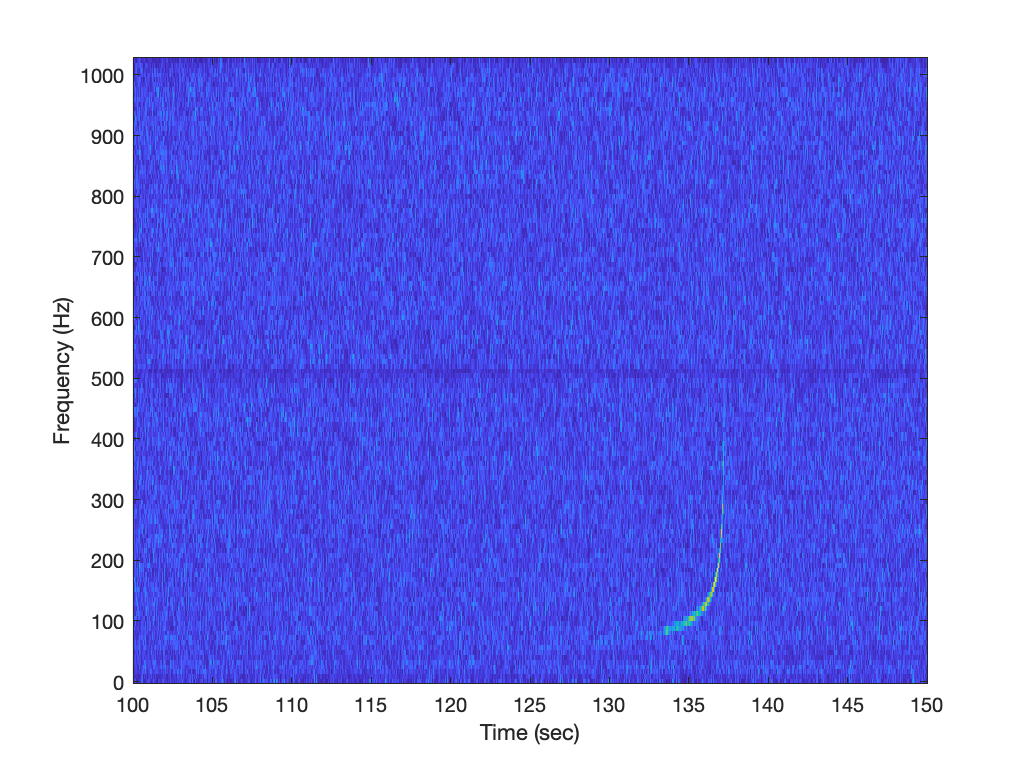

%Multiply by the desired SNR and add it to the conditioned data
clnCond_injSig = reshape(injSigSNR * injSig_clnCond, size(clnCond_Strain)) + clnCond_Strain;

figure;
[S,F,T] = spectrogram(clnCond_injSig, 256,[],[],clnCond_fsmpl);
imagesc(T,F,abs(S)); axis xy;
xlim([clnCond_injSig_TOA,clnCond_injSig_TOA+50]);
xlabel('Time (sec)');
ylabel('Frequency (Hz)');


%Matched filter output
clnCond_mfltrOut = mfltr(fft(clnCond_injSig), ...
                                            clnCond_whtTF,...
                                            clnCond_fsmpl,sigParams);

Approximate signal length 37.2631 sec


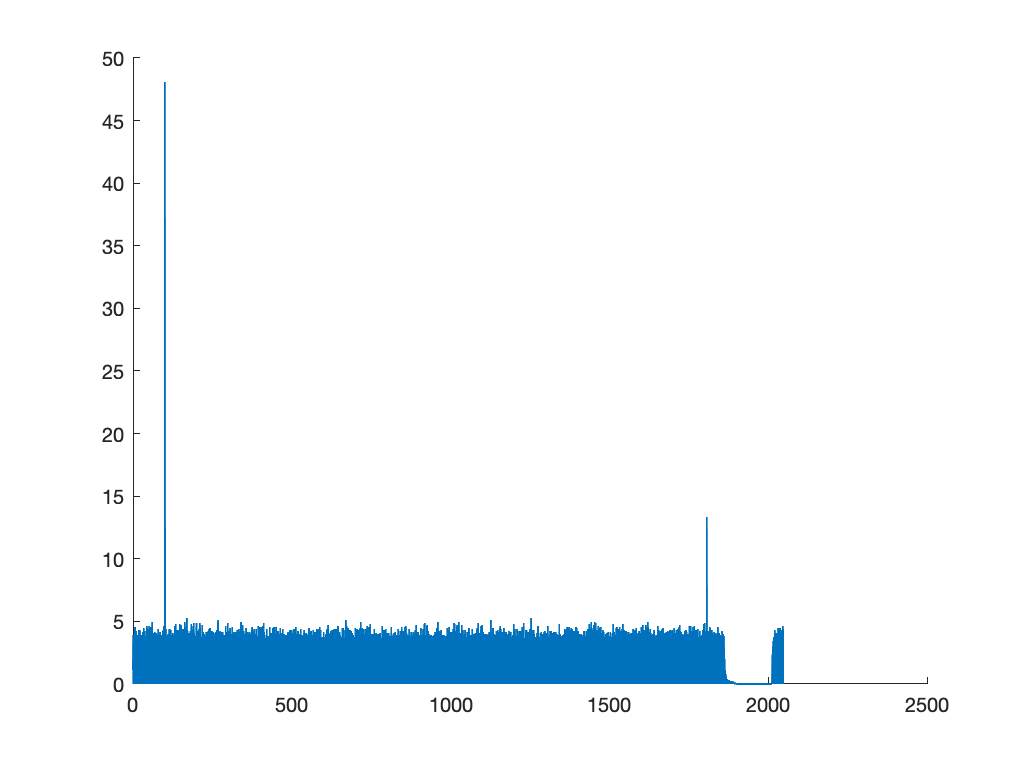

figure;
hold on;
plot(clnCond_tVec,clnCond_mfltrOut, 'LineWidth',1.0);

% title(['M1 = ',num2str(sigParams.mass1),', M2=',num2str(sigParams.mass2),...
%        ' f_{min}=',num2str(sigParams.fMin)]);
% legend('SHAPES residual','BayesWave residual');
% xlim([334.1, 334.4]);
% ylim([0,22]);
% xlabel('time (sec) + 1187008512 sec','FontSize',14);
% ylabel('Matched filter SNR','FontSize',14);